clear all

clf
ultrafinetbl = readtable("/Users/2fast2kavin/Desktop/Atmospheric Aerosol Group/EPCAPE/UCVF plot/ucvf vs ultrafine salt.xlsx")

ultrafinetbl = 49×3 table
    DateAndTime    avgUCVF    avgUfineSalt
    ___________    _______    ____________

    27-Apr-2023    0.94304     0.0014215  
    28-Apr-2023    0.95578     0.0022532  
    29-Apr-2023    0.92483     0.0067298  
    30-Apr-2023    0.86966     0.0055114  
    01-May-2023    0.83356     0.0073929  
    02-May-2023    0.42491      0.035637  
    03-May-2023    0.31614      0.022904  
    04-May-2023    0.26324      0.036252  
    05-May-2023    0.26976      0.040623  
    06-May-2023    0.41163       0.01742  
    07-May-2023    0.29702       0.02562  
    08-May-2023    0.42385      0.034664  
    09-May-2023    0.45262      0.069249  
    10-May-2023     0.3201      0.080159  
    11-May-2023    0.52887      0.045689  
    12-May-2023    0.64112      0.031882  


LANLdata_HOA_rBC = readtable("/Users/2fast2kavin/Desktop/Atmospheric Aerosol Group/EPCAPE/UCVF plot/LANL_UCVF_Correlations.xlsx")

LANLdata_HOA_rBC = 2912×4 table
        DateTime_UTC          UCVF      HOAMass_ugM_3_    rBCMass_ugM_3_
    ____________________    ________    ______________    ______________

    16-Feb-2023 00:00:00     0.19545         NaN               NaN      
    16-Feb-2023 03:00:00     0.24994         NaN               NaN      
    16-Feb-2023 06:00:00     0.34375         NaN               NaN      
    16-Feb-2023 09:00:00     0.33526         NaN               NaN      
    16-Feb-2023 12:00:00     0.22235         NaN               NaN      
    16-Feb-2023 15:00:00     0.16864         NaN               NaN      
    16-Feb-2023 18:00:00     0.24687         NaN               NaN      
    16-Feb-2023 21:00:00     0.22186         NaN               NaN      
    17-Feb-2023 00:00:00     0.29311         NaN               NaN      
    17-Feb-2023 03:00:00    

OHvsUCVF = readtable("EPCAPE_overview_UCLAgraph.csv")

OHvsUCVF = 71×11 table
     sampleId      OH_burst_25000_vv_dilution_ratio_uM    RH    UCVF24    UCVF6    Var6       Averages        Var8    Var9    Var10    Var11
    ___________    ___________________________________    __    ______    _____    ____    _______________    ____    ____    _____    _____

    {'822'    }                   0.27                    77     0.29      0.3     NaN     {0×0 char     }     NaN    NaN      NaN      NaN 
    {'822-823'}                   0.28                    85     0.59     0.56     NaN     {'all'        }    0.25     72     0.48     0.44 
    {'826'    }                    0.2

load kavin_UCVF.mat
KAVIN_TABLE

KAVIN_TABLE = 3174×7 table
          Time           SR-OOA    MO-OOA    f44    NO3    SO4    UCVF
    _________________    ______    ______    ___    ___    ___    ____

    01/15/23 00:00:00     NaN       NaN      NaN    NaN    NaN    NaN 
    01/15/23 03:00:00     NaN       NaN      NaN    NaN    NaN    NaN 
    01/15/23 06:00:00     NaN       NaN      NaN    NaN    NaN    NaN 
    01/15/23 09:00:00     NaN       NaN      NaN    NaN    NaN    NaN 
    01/15/23 12:00:00     NaN       NaN      NaN    NaN    NaN    NaN 
    01/15/23 15:00:00     NaN       NaN      NaN    NaN    NaN    NaN 
    01/15/23 18:00:00     NaN       NaN      NaN    NaN    NaN    NaN 
    01/15/23 21:00:00     NaN       NaN      NaN    NaN    NaN    NaN 
    01/16/23 00:00:00   

dmoso = month(KAVIN_TABLE.Time) + (year(KAVIN_TABLE.Time) -2023)*12

dmoso =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1
     1


NewMexico = readtable("dD_UCVFreal.xlsx")

NewMexico = 59576×3 table
                time                   dD                UCVF         
    _____________________________    _______    ______________________

    {'2023-07-14 22:20:00+00:00'}    -83.798    {'0.6737728163944444'}
    {'2023-07-14 22:25:00+00:00'}    -82.897    {'0.6744231556333333'}
    {'2023-07-14 22:30:00+00:00'}    -83.948    {'0.6750734948722222'}
    {'2023-07-14 22:35:00+00:00'}    -83.195    {'0.6757238341111111'}
    {'2023-07-14 22:40:00+00:00'}    -84.012    {'0.6763741733499999'}
    {'2023-07-14 22:45:00+00:00'}     -84.13    {'0.6770245125888888'}
    {'2023-07-14 22:50:00+00:00'}    -83.669    {'0.6776748518277778'}
    {'2023-07-14 22:55:00+00:00'}    -84.767    {'0.6783251910666667'}
    {'2023-07-14 23:00:00+00:00'}    -83.257    {'0.6789755303055556'}
    {'2023-07-14 23:05:00+00:00'}     -84.77    {'0.6796258695444445'}
    {'2023-07-14 23

stringythingy = extractBetween(string(NewMexico.time),1,19);
ddD = datetime(stringythingy,"Format","dd-MMM-uuuu HH:mm:ss");
julydD = NewMexico.dD(month(ddD) == 7)

julydD =   -83.7980
  -82.8966
  -83.9476
  -83.1952
  -84.0122
  -84.1299
  -83.6694
  -84.7666
  -83.2571
  -84.7702
  -84.3166
  -85.1599
  -83.7714
  -85.0050
  -84.1197


julyUCVF = str2double(string(NewMexico.UCVF(month(ddD) == 7)))

julyUCVF =     0.6738
    0.6744
    0.6751
    0.6757
    0.6764
    0.6770
    0.6777
    0.6783
    0.6790
    0.6796
    0.6803
    0.6809
    0.6816
    0.6822
    0.6842



elavarasi = readtable("Cloud aqueous reaction data (Petters and Liggio) - April.csv")

elavarasi = 22×11 table
    UCVF     AOS       Var3      AOSFthickly_90nm      Var5      UndenudedKappaAtS_0_2_      Var7       UndenudedKappaAtS_0_4_      Var9       Var10                              Var11                          
    ____    ______    _______    ________________    ________    ______________________    _________    ______________________    _________    _____    _________________________________________________________

     NaN       NaN        NaN            NaN              NaN               NaN                  NaN               NaN                  NaN     NaN     {0×0 char                    

clf

model = fitlm(LANLdata_HOA_rBC.UCVF,LANLdata_HOA_rBC.HOAMass_ugM_3_);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit1 = linspace(min(LANLdata_HOA_rBC.UCVF), max(LANLdata_HOA_rBC.UCVF), 100);
yFit1 = feval(model, xFit1);

[r,p]=corrcoef(LANLdata_HOA_rBC.UCVF, LANLdata_HOA_rBC.HOAMass_ugM_3_,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string1=append(str1,str2);

model = fitlm(LANLdata_HOA_rBC.UCVF,LANLdata_HOA_rBC.rBCMass_ugM_3_);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit2 = linspace(min(LANLdata_HOA_rBC.UCVF), max(LANLdata_HOA_rBC.UCVF), 100);
yFit2 = feval(model, xFit2);

[r,p]=corrcoef(LANLdata_HOA_rBC.UCVF, LANLdata_HOA_rBC.rBCMass_ugM_3_,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string2=append(str1,str2);

%%%%%%TILE 2


model = fitlm(KAVIN_TABLE.UCVF(dmoso <= 6 & dmoso >= 4),KAVIN_TABLE.("MO-OOA")(dmoso <= 6 & dmoso >= 4));
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit3 = linspace(min(KAVIN_TABLE.UCVF(dmoso <= 6 & dmoso >= 4)), max(KAVIN_TABLE.UCVF(dmoso <= 6 & dmoso >= 4)), 100);
yFit3 = feval(model, xFit3);

[r,p]=corrcoef(KAVIN_TABLE.UCVF(dmoso <= 6 & dmoso >= 4), KAVIN_TABLE.("MO-OOA")(dmoso <= 6 & dmoso >= 4),'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string3=append(str1,str2);

model = fitlm(KAVIN_TABLE.UCVF,KAVIN_TABLE.NO3);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit4 = linspace(min(KAVIN_TABLE.UCVF), max(KAVIN_TABLE.UCVF), 100);
yFit4 = feval(model, xFit4);

[r,p]=corrcoef(KAVIN_TABLE.UCVF, KAVIN_TABLE.NO3,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string4=append(str1,str2);

model = fitlm(KAVIN_TABLE.UCVF,KAVIN_TABLE.SO4);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit5 = linspace(min(KAVIN_TABLE.UCVF), max(KAVIN_TABLE.UCVF), 100);
yFit5 = feval(model, xFit5);

[r,p]=corrcoef(KAVIN_TABLE.UCVF, KAVIN_TABLE.SO4,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string5=append(str1,str2);

model = fitlm(KAVIN_TABLE.UCVF(dmoso <= 6 & dmoso >= 4),KAVIN_TABLE.("SR-OOA")(dmoso <= 6 & dmoso >= 4));
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit6 = linspace(min(KAVIN_TABLE.UCVF(dmoso <= 6 & dmoso >= 4)), max(KAVIN_TABLE.UCVF(dmoso <= 6 & dmoso >= 4)), 100);
yFit6 = feval(model, xFit6);

[r,p]=corrcoef(KAVIN_TABLE.UCVF(dmoso <= 6 & dmoso >= 4), KAVIN_TABLE.("SR-OOA")(dmoso <= 6 & dmoso >= 4),'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string6 =append(str1,str2);

model = fitlm(elavarasi.UCVF,elavarasi.AOS);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit7 = linspace(min(elavarasi.UCVF), max(elavarasi.UCVF), 100);
yFit7 = feval(model, xFit7);

[r,p]=corrcoef(elavarasi.UCVF, elavarasi.AOS,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string7=append(str1,str2);


model = fitlm(KAVIN_TABLE.UCVF,KAVIN_TABLE.f44);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit8 = linspace(min(KAVIN_TABLE.UCVF), max(KAVIN_TABLE.UCVF), 100);
yFit8 = feval(model, xFit8);

[r,p]=corrcoef(KAVIN_TABLE.UCVF, KAVIN_TABLE.f44,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string8=append(str1,str2);

%%%%TILE 3

model = fitlm(julyUCVF,julydD);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit9 = linspace(min(julyUCVF), max(julyUCVF), 100);
yFit9 = feval(model, xFit9);

[r,p]=corrcoef(julyUCVF, julydD,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string9=append(str1,str2);


model = fitlm(OHvsUCVF.UCVF24,OHvsUCVF.OH_burst_25000_vv_dilution_ratio_uM);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit10 = linspace(min(OHvsUCVF.UCVF24), max(OHvsUCVF.UCVF24), 100);
yFit10 = feval(model, xFit10);

[r,p]=corrcoef(OHvsUCVF.UCVF24, OHvsUCVF.OH_burst_25000_vv_dilution_ratio_uM,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string10=append(str1,str2);

%xL=xlim; xdiff = diff(xlim); xpos = xL(1) + 0.7*xdiff; 
%yL=ylim; ydiff = diff(ylim); ypos= yL(1) + 0.9*ydiff;
%text(xpos,ypos,str,'HorizontalAlignment','left','VerticalAlignment','top','FontSize',10)


%title("Isotopes and Oxidants")

model = fitlm(elavarasi.UCVF,elavarasi.AOSFthickly_90nm);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit11 = linspace(min(elavarasi.UCVF), max(elavarasi.UCVF), 100);
yFit11 = feval(model, xFit11);

[r,p]=corrcoef(elavarasi.UCVF,elavarasi.AOSFthickly_90nm,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string11=append(str1,str2);

model = fitlm(OHvsUCVF.UCVF24,OHvsUCVF.RH);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit12 = linspace(min(OHvsUCVF.UCVF24), max(OHvsUCVF.UCVF24), 100);
yFit12 = feval(model, xFit12);

[r,p]=corrcoef(OHvsUCVF.UCVF24,OHvsUCVF.RH,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string12=append(str1,str2);


model = fitlm(julyUCVF,julydD);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit13 = linspace(min(julyUCVF), max(julyUCVF), 100);
yFit13 = feval(model, xFit13);

[r,p]=corrcoef(julyUCVF,julydD,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string13=append(str1,str2);

model = fitlm(ultrafinetbl.avgUCVF,ultrafinetbl.avgUfineSalt);
b = model.Coefficients.Estimate(1);
m = model.Coefficients.Estimate(2);
xFit14 = linspace(min(ultrafinetbl.avgUCVF), max(ultrafinetbl.avgUCVF), 100);
yFit14 = feval(model, xFit14);

[r,p]=corrcoef(ultrafinetbl.avgUCVF,ultrafinetbl.avgUfineSalt,'rows','pairwise');
r=r(2,1);
p=p(2,1);
str1="r = ";
str2=string(round(r,2));
string14=append(str1,str2);


discso4index = discretize(KAVIN_TABLE.UCVF,0:0.05:1);
discso4 = zeros(489,20);
for i = 1:20
    discsize = size(KAVIN_TABLE.SO4(discso4index == i));
    discso4(1:discsize(1),i) = KAVIN_TABLE.SO4(discso4index == i);
end
meanso4 = mean(discso4,1,'omitmissing');
stdso4 = std(discso4,[],1,'omitmissing');

discso4index = discretize(KAVIN_TABLE.UCVF,0:0.1:1);
discMO = zeros(489,10);
for i = 1:10
    discsize = size(KAVIN_TABLE.("MO-OOA")(discso4index == i));
    discMO(1:discsize(1),i) = KAVIN_TABLE.('MO-OOA')(discso4index == i);
end
meanMO = mean(discMO,1,'omitmissing');
stdMO = std(discMO,[],1,'omitmissing');

discso4index = discretize(KAVIN_TABLE.UCVF,0:0.1:1);
discSR = zeros(489,10);
for i = 1:10
    discsize = size(KAVIN_TABLE.("SR-OOA")(discso4index == i));
    discSR(1:discsize(1),i) = KAVIN_TABLE.('SR-OOA')(discso4index == i);
end
meanSR = mean(discSR,1,'omitmissing');
stdSR = std(discSR,[],1,'omitmissing');

discso4index = discretize(KAVIN_TABLE.UCVF,0:0.1:1);
discf44 = zeros(489,10);
for i = 1:10
    discsize = size(KAVIN_TABLE.f44(discso4index == i));
    discf44(1:discsize(1),i) = KAVIN_TABLE.f44(discso4index == i);
end
meanf44 = mean(discf44,1,'omitmissing');
stdf44 = std(discf44,[],1,'omitmissing');

discso4index = discretize(KAVIN_TABLE.UCVF,0:0.1:1);
discNO3 = zeros(489,10);
for i = 1:10
    discsize = size(KAVIN_TABLE.NO3(discso4index == i));
    discNO3(1:discsize(1),i) = KAVIN_TABLE.NO3(discso4index == i);
end
meanNO3 = mean(discNO3,1,'omitmissing');
stdNO3 = std(discNO3,[],1,'omitmissing');


clf
tiledlayout(8,4,'TileSpacing','compact')

nexttile(1,[4,3])
plot(xFit7,yFit7)
hold on
plot(xFit5,yFit5.*2 + 3)
plot(xFit3,yFit3.*5 + 2.5)
plot(xFit6,yFit6.*7 + 1.8)
plot(xFit8,yFit8.*25 - 3)
plot(xFit11,yFit11.*15-4)

scatter(elavarasi.UCVF,elavarasi.AOS,[20],[0, 0.4470, 0.7410],HandleVisibility='off',Marker='.')
s = scatter(KAVIN_TABLE.UCVF,KAVIN_TABLE.SO4.*2 + 3,[20],[0.8500, 0.3250, 0.0980],HandleVisibility='off',Marker='.')

s =   Scatter with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3174 double)
              YData: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3174 double)
           SizeData: 20
              CData: [0.8500 0.3250 0.0980]

  Show 

alpha(s,0.1)
s2 = scatter(KAVIN_TABLE.UCVF,KAVIN_TABLE.('MO-OOA').*5 + 2.5,[20],[0.9290, 0.6940, 0.1250],HandleVisibility='off',Marker='.')

s2 =   Scatter with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3174 double)
              YData: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3174 double)
           SizeData: 20
              CData: [0.9290 0.6940 0.1250]

  Show 

alpha(s2,0.3)
s3 = scatter(KAVIN_TABLE.UCVF,KAVIN_TABLE.('SR-OOA').*7 + 1.8,[20],[0.4940, 0.1840, 0.5560],HandleVisibility="off",Marker = '.')

s3 =   Scatter with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3174 double)
              YData: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3174 double)
           SizeData: 20
              CData: [0.4940 0.1840 0.5560]

  Show 

alpha(s3,0.1)
s4 = scatter(KAVIN_TABLE.UCVF,KAVIN_TABLE.f44.*25 -3,[20],[0.4660, 0.6740, 0.1880],HandleVisibility="off",Marker = '.')

s4 =   Scatter with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3174 double)
              YData: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3174 double)
           SizeData: 20
              CData: [0.4660 0.6740 0.1880]

  Show 

alpha(s4,0.1)
s6 = scatter(elavarasi.UCVF,elavarasi.AOSFthickly_90nm.*15-4,[20],[0.3010, 0.7450, 0.9330],HandleVisibility="off",Marker = '.')

s6 =   Scatter with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [NaN 0 0.0500 0.1000 0.1500 0.2000 0.2500 0.3000 0.3500 0.4000 0.4500 0.5000 0.5500 0.6000 0.6500 0.7000 0.7500 0.8000 0.8500 0.9000 0.9500 1]
              YData: [NaN 0.4900 -1.4534 0.7887 0.4744 0.2786 0.4975 0.8852 0.7269 1.0309 2.6880 2.3099 1.6561 2.0687 2.3091 3.7212 2.6405 1.7130 1.1937 1.6991 1.7704 -0.5908]
           SizeData: 20
              CData: [0.3010 0.7450 0.9330]

  Show all properties


alpha(s6,0.9)
no3index = KAVIN_TABLE.NO3.*95 -29 < 6

no3index = 3174×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


hold off
ylim([0 7])
ylabel("Arbitrary Units")
yticklabels("")
lgnd = legend("AOS, "+ string7,"SO4, "+string5,"MO-OOA, "+string3,"SR-OOA, " + string6,"f44, "+string8,"FThickly, "+string11)

lgnd =   Legend (AOS, r = 0.89, SO4, r = 0.47, MO-OOA, r = 0.43, SR-OOA, r = 0.4, f44, r = 0.38, FThickly, r = 0.46) with properties:

         String: {'AOS, r = 0.89'  'SO4, r = 0.47'  'MO-OOA, r = 0.43'  'SR-OOA, r = 0.4'  'f44, r = 0.38'  'FThickly, r = 0.46'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 7.2000
       Position: [0.4548 0.6844 0.2315 0.2090]
          Units: 'normalized'

  Show all properties


lgnd.FontSize = 5

lgnd =   Legend (AOS, r = 0.89, SO4, r = 0.47, MO-OOA, r = 0.43, SR-OOA, r = 0.4, f44, r = 0.38, FThickly, r = 0.46) with properties:

         String: {'AOS, r = 0.89'  'SO4, r = 0.47'  'MO-OOA, r = 0.43'  'SR-OOA, r = 0.4'  'f44, r = 0.38'  'FThickly, r = 0.46'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 5
       Position: [0.4977 0.7318 0.1887 0.1616]
          Units: 'normalized'

  Show all properties


text(0.03, 0.97*7,'A')
xticklabels([""])
xticks([0:0.1:1])

nexttile(17,[2,3])
plot(xFit1,yFit1)
hold on
plot(xFit2,yFit2)
plot(xFit14,yFit14)
sone = scatter(LANLdata_HOA_rBC.UCVF,LANLdata_HOA_rBC.HOAMass_ugM_3_.*2,[20],[0, 0.4470, 0.7410],HandleVisibility='off',Marker='.')

sone =   Scatter with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [0.1955 0.2499 0.3438 0.3353 0.2224 0.1686 0.2469 0.2219 0.2931 0.2370 0.2115 0.2115 0.0659 0.0884 0.1243 0.0887 0.0605 0.0677 0.0425 0.0099 0.1318 0.1344 0.0481 0.0619 0.1471 0.1612 0.1877 0.2434 0.2221 0.1564 … ] (1×2912 double)
              YData: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×2912 double)
           SizeData: 20
              CData: [0 0.4470 0.7410]

  Show 

alpha(sone,0.4)
stwo = scatter(LANLdata_HOA_rBC.UCVF,LANLdata_HOA_rBC.rBCMass_ugM_3_.*2,[20],[0.8500, 0.3250, 0.0980],HandleVisibility='off',Marker='.')

stwo =   Scatter with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [0.1955 0.2499 0.3438 0.3353 0.2224 0.1686 0.2469 0.2219 0.2931 0.2370 0.2115 0.2115 0.0659 0.0884 0.1243 0.0887 0.0605 0.0677 0.0425 0.0099 0.1318 0.1344 0.0481 0.0619 0.1471 0.1612 0.1877 0.2434 0.2221 0.1564 … ] (1×2912 double)
              YData: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×2912 double)
           SizeData: 20
              CData: [0.8500 0.3250 0.0980]

  Show 

alpha(stwo,0.5)
sthr = scatter(ultrafinetbl.avgUCVF,ultrafinetbl.avgUfineSalt,[20],[0.9290, 0.6940, 0.1250]	,HandleVisibility='off',Marker='.')

sthr =   Scatter with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [0.9430 0.9558 0.9248 0.8697 0.8336 0.4249 0.3161 0.2632 0.2698 0.4116 0.2970 0.4238 0.4526 0.3201 0.5289 0.6411 0.8157 0.9617 0.9279 0.7413 0.8629 0.8938 0.8417 0.9090 0.9265 0.9629 0.9593 0.9557 0.7775 0.6165 … ] (1×49 double)
              YData: [0.0014 0.0023 0.0067 0.0055 0.0074 0.0356 0.0229 0.0363 0.0406 0.0174 0.0256 0.0347 0.0692 0.0802 0.0457 0.0319 0.0123 0.0030 0.0017 0.0019 0.0012 0.0027 0.0041 0.0032 7.8957e-04 6.8721e-04 0.0014 0.0142 0.0364 … ] (1×49 double)
           SizeData: 20
              CData: [0.9290 0.6940 0.1250]

  Show 

alpha(sthr,0.5)
hold off
ylabel("Arbitrary Units")
yticklabels("")
legend("rBC, "+ string1,"HOA, "+ string2,"NaCl2, "+ string3, FontSize=5)
text(0.03, 0.95*0.6,'B')
xticklabels("")
ylim([0 0.6])
xticks([0:0.1:1])

nexttile(25,[2,3])
plot(xFit10,yFit10.*20)
hold on
plot(xFit13,yFit13+ 85)
suno = scatter(julyUCVF,julydD+85,[20],[0.8500, 0.3250, 0.0980],HandleVisibility='off',Marker='.')

suno =   Scatter with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [0.6738 0.6744 0.6751 0.6757 0.6764 0.6770 0.6777 0.6783 0.6790 0.6796 0.6803 0.6809 0.6816 0.6822 0.6842 0.6862 0.6882 0.6901 0.6921 0.6941 0.6961 0.6980 0.7000 0.7020 0.7040 0.7059 0.7079 0.7099 0.7119 0.7138 … ] (1×4916 double)
              YData: [1.2020 2.1034 1.0524 1.8048 0.9878 0.8701 1.3306 0.2334 1.7429 0.2298 0.6834 -0.1599 1.2286 -0.0050 0.8803 0.2221 0.5002 -0.2402 0.2435 -0.3652 0.5037 0.3651 0.8796 0.7852 0.7733 -0.5555 0.2973 -0.7582 -1.0576 … ] (1×4916 double)
           SizeData: 20
              CData: [0.8500 0.3250 0.0980]

  Show 

alpha(suno,0.1)
sdos = scatter(OHvsUCVF.UCVF24,OHvsUCVF.OH_burst_25000_vv_dilution_ratio_uM.*20,[20],[0, 0.4470, 0.7410],HandleVisibility='off',Marker='.')

sdos =   Scatter with properties:

             Marker: '.'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
              XData: [0.2900 0.5900 0.5900 0.5100 0.5900 0.4900 0.3600 0.5200 0.3000 0.4700 0.5500 0.4900 0.4000 0.5400 0.5200 0.5400 0.4200 0.3900 0.2200 0.1200 0.1800 0.7000 0.7600 0.9000 0.9000 0.7600 0.4500 0.6600 0.1800 0.7800 … ] (1×71 double)
              YData: [5.4000 5.6000 4 2.4000 3 3.6000 3 8.4000 3.6000 5.6000 4.4000 3.6000 6 1 4 4 2.2000 5.2000 6.4000 2.8000 3.6000 2.8000 1.8000 2.2000 1.4000 3 5 7 6.4000 4.6000 4.8000 6.4000 9.4000 12.4000 7 7.8000 1.2000 2.6000 3 1 … ] (1×71 double)
           SizeData: 20
              CData: [0 0.4470 0.7410]

  Show 

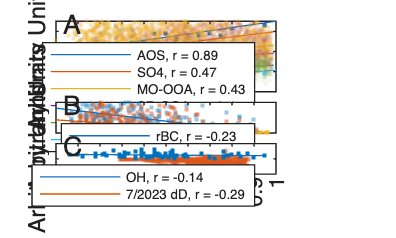

alpha(sdos,1)
hold off
ylabel("Arbitrary Units")
yticklabels("")
legend("OH, "+ string10,"7/2023 dD, "+string13, FontSize=5)
text(0.03, 0.95*40-20,'C')
ylim([-20 20])
xticks([0:0.1:1])
xticklabels([0:0.1:1])